## Section 1

### 1.

rng(1)
pkt_size = 10;
smpl_per_symbl = 8;
b_tx = bit_gen(10, 2)

b_tx =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


### 2.

modulation = 'pam';
M = 4;
k = log2(M);
b_gray = gray_code(k)

b_gray =      0     0
     0     1
     1     1
     1     0


sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_gray == b_tx(i,:),2) == 2);
end
sym_idx

sym_idx =      1
     3
     1
     2
     1
     2
     1
     2
     1
     4


[cons, Es_avg] = constellation(M, modulation)

cons =    -1.3416
   -0.4472
    0.4472
    1.3416


Es_avg = 1

mod_sym = zeros(size(sym_idx));
for i=1:size(sym_idx,1)
    mod_sym(i,1) = cons(sym_idx(i,1));
end
mod_sym

mod_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


### 3.

fs = 1;
pulse_name = 'triangle'

pulse_name = 'triangle'

pulse_shape_mode = 'conv'

pulse_shape_mode = 'conv'

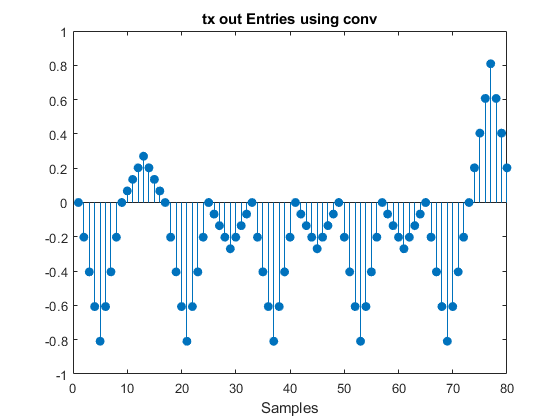

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
stem(tx_smpl, 'filled')
title('tx out Entries using conv')
xlabel('Samples')

fs = 1;
pulse_name = 'triangle'

pulse_name = 'triangle'

pulse_shape_mode = 'kron'

pulse_shape_mode = 'kron'

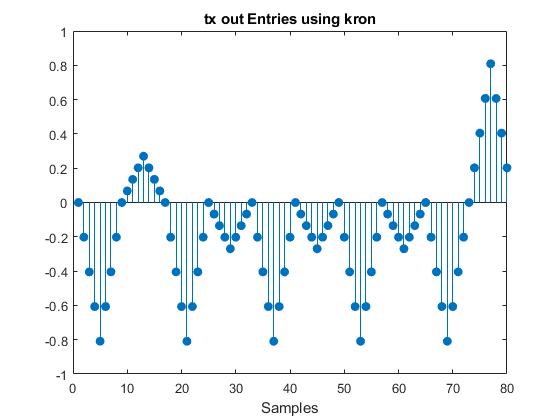

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
stem(tx_smpl, 'filled')
title('tx out Entries using kron')
xlabel('Samples')

## Section 2

### 1.

[p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl);
rx_smpl = tx_smpl;

corr_match using correlator

rx_mode = 'correlator'

rx_mode = 'correlator'

rx_sym = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode)

rx_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


corr_match using matched filter

rx_mode = 'matched_filter'

rx_mode = 'matched_filter'

rx_sym = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode)

rx_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


### 2.

[det_sym] = min_dist_detector(rx_sym, cons)

det_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode)

det_sym_idx =      1
     3
     1
     2
     1
     2
     1
     2
     1
     4


rx_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


b_gray;
b_tx

b_tx =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


det_bit = b_gray(det_sym_idx,:)

det_bit =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


Demodulation system is working correcty. 